# Graph capillaries from OCT microangiogram

## 1. Initiate.

Select microangiogram data to load. Please indicate the path to the .mat file containing the microangiogram. For branching order analysis, please also include the corresponding structural (intensity) data.

clear;
samp_interval = 1.5; %pixels in xy plane are 1.5um 
pathraw_micro = 'microangiogram_example'; %path to microangiogram 

% Do you want to perform branching order analysis? 

branch_order = 'y'; %'y' for yes, 'n' for no. 

% If yes, please indicate path to structural (intensity) data
if branch_order == 'y'
    pathraw_struct = 'intensity_example'; %structural (intensity)
end

pathdata = 'D:/sstefan/microangiogram_analyzed'; % path to save reconstructed data
if isempty(dir(pathdata))
    mkdir(pathdata)
end

disp('Init complete')

Init complete


## 2. Load microangiogram data 

disp('Data loading ...');

Data loading ...


DD = load(pathraw_micro);
DD = struct2cell(DD);
DD = DD{1};

if branch_order == 'y'
    II = load(pathraw_struct);
    II = struct2cell(II);
    II = II{1};
end


disp([datestr(now,'HH:MM') ' data loaded.']);

09:40 data loaded.


load('net_reg'); %regression (EnhVess)
load('net12_16_final.mat'); %segmentation (SegVess)


## 3. Select Region of Interest (ROI)

- If desired, sellect a region of interest by drawing a rectangle. If you wish to process the entire image, skip this section.

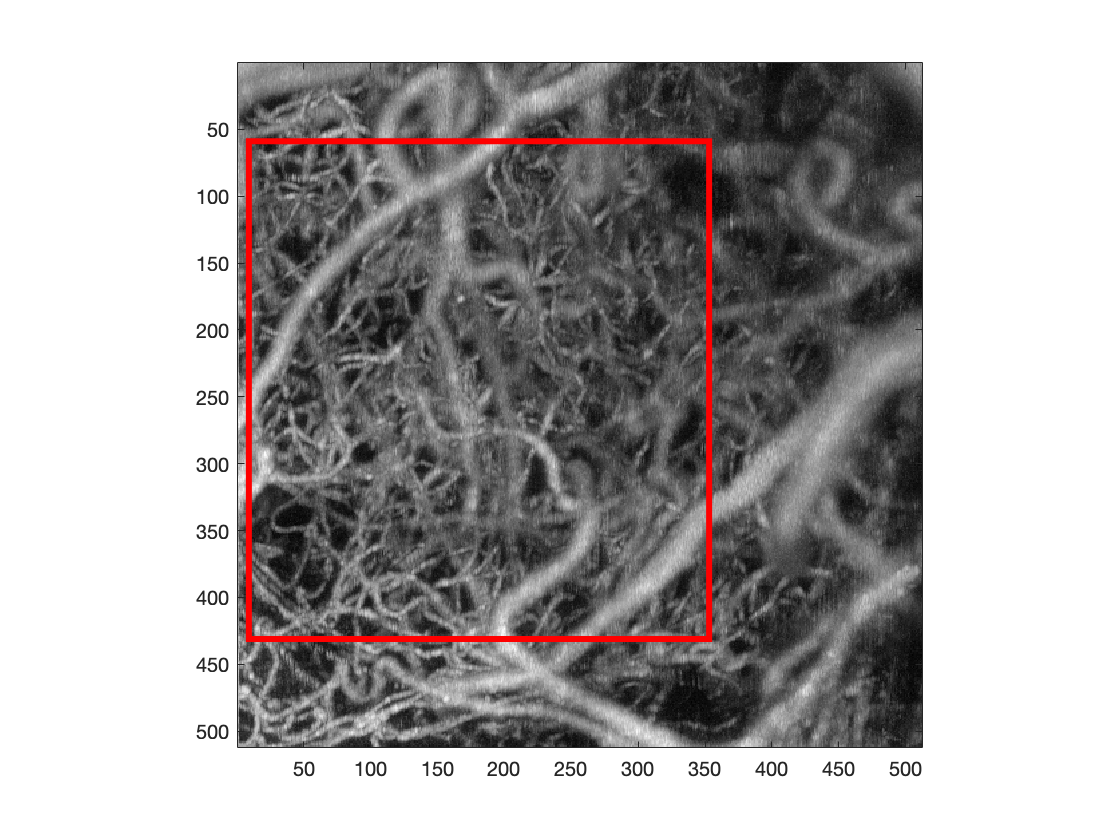


Select_ROI;

mip = squeeze(max(log(DD),[],1));
figure(1); imagesc(squeeze((mip)))
colormap(gray)
axis image
hold on; rectangle('Position', [y1, x1, y2-y1, x2-x1], 'EdgeColor','r', 'LineWidth', 3);


DD = DD(:,x1:x2,y1:y2);
II = II(:,x1:x2, y1:y2);

## 4. Apply enhancement CNN (EnhVess).

- Data is pre-processed using filtering, and a microangiogram is enhanced using EnhVess.

- Takes about ~1min

DD = medfilt3(DD, [3 3 3]);
logDD = log(DD);
logDD = mat2gray(logDD);

[s1, s2, s3] = size(DD);
m1 = mod([s1 s2 s3],32);
p1 = 0; p2 = 0; p3 = 0;

if m1(1) > 0
    p1 = 32-m1(1);
end

if m1(2) > 0
    p2 = 32-m1(2);
end

if m1(3) > 0
    p3 = 32-m1(3);
end

if sum(m1) > 0
    logDD = padarray(logDD, [p1 p2 p3], 'post');
end


Enh = activations(net_reg, logDD, 'regressionoutput', 'executionenvironment', 'cpu');
Enh = Enh(1:s1,1:s2,1:s3);
logDD = logDD(1:s1,1:s2,1:s3);



## 5. Crop Depth

Use the slider to scan through the depth, and assess the depth of interest - where does the microvascular bed start and end? Once you quit the slider, select the depth of interest using the Intensity profile to guide you.

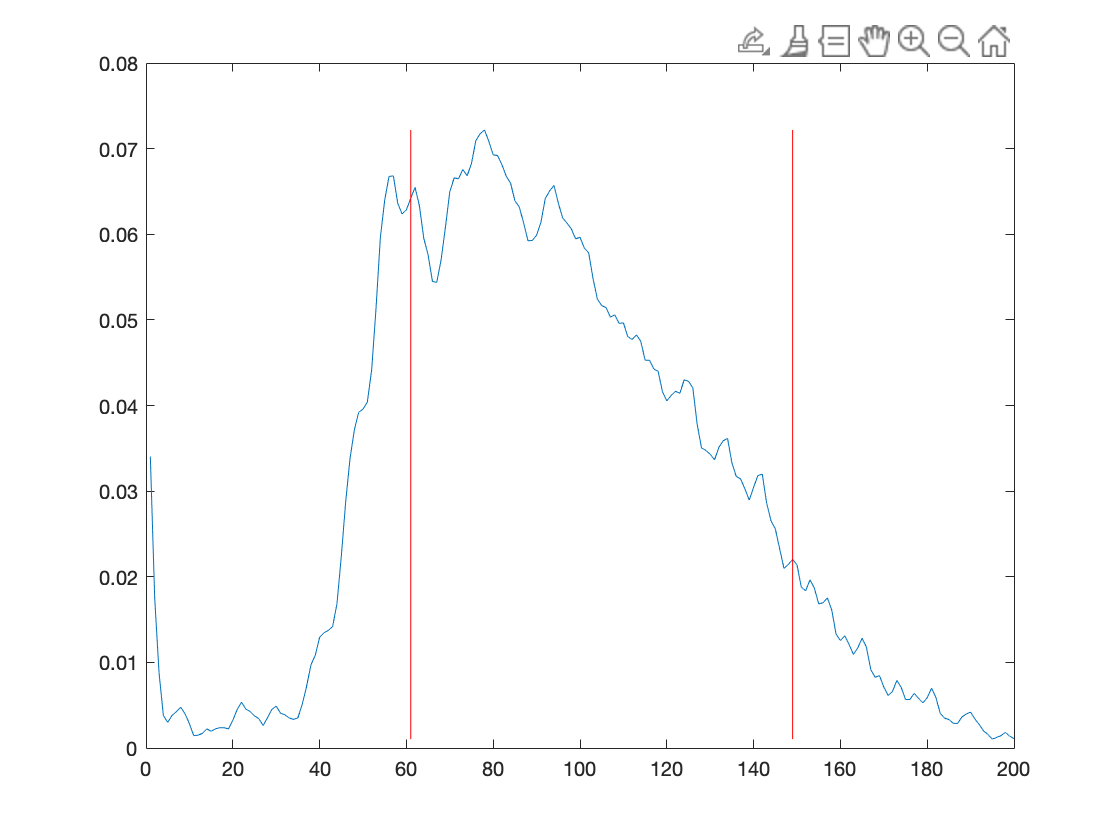

GUI_slider(permute(Enh, [2 3 1]));

Crop_depth

Enh = Enh(z1:z2,:,:);
logDD = logDD(z1:z2,:,:);
II = II(z1:z2,:,:);


### 5. Apply Segmentation network (SegVess)

- Takes about ~3min

tic
[s1, s2, s3] = size(Enh);
m1(1) = mod(s1,12);
m1(2) = mod(s2,16);
m1(3) = mod(s3,16);
p1 = 0; p2 = 0; p3 = 0;

if m1(1) > 0
    p1 = 12-m1(1);
end

if m1(2) > 0
    p2 = 16-m1(2);
end

if m1(3) > 0
    p3 = 16-m1(3);
end

if sum(m1) > 0
    Enh = padarray(Enh, [p1 p2 p3], 'post');
end


val = [48 32 24 26 12];
v1 = []; v2 = []; v3 = [];

for i = 1:length(val)
    
    m = mod(size(Enh),val(i));

    if m(1) == 0 && isempty(v1) 
        v1 = val(i);
    end

    if m(2) == 0 && isempty(v2) 
        v2 = val(i);
    end

    if m(3) == 0 && isempty(v3) 
        v3 = val(i);
    end

end



l1 = size(Enh,1)/v1;

l2 = size(Enh,2)/v2;
l3 = size(Enh,3)/v3;

seg = zeros(size(Enh));
for i = 1:l1
    for j = 1:l2
        for k = 1:l3
            seg((v1*(i-1) + 1):v1*i, (v2*(j-1) + 1):v2*j,(v3*(k-1) + 1):v3*k) = semanticseg(Enh((v1*(i-1) + 1):v1*i, (v2*(j-1) + 1):v2*j,(v3*(k-1) + 1):v3*k), net12_16_final);
        end
    end
end

seg = double(seg) - 1;
seg = imclose(seg,ones(3,3,3));

seg = seg(1:s1,1:s2,1:s3);
Enh = Enh(1:s1,1:s2,1:s3);


seg = imgaussfilt3(seg,1) > 0.3;

mip = squeeze(max(seg,[],1));
figure; imagesc(squeeze((mip)))
colormap(gray)
axis image
toc

## 6. Apply connectivity-enhancing network (ConVess) 

- Connectivity-enhancing network uses underlying data (OCTA and enhanced OCTA) to guide gap correction of the segmentation from the previous step.

- Edges are smoothed, and isolated components smaller than 50px are removed.

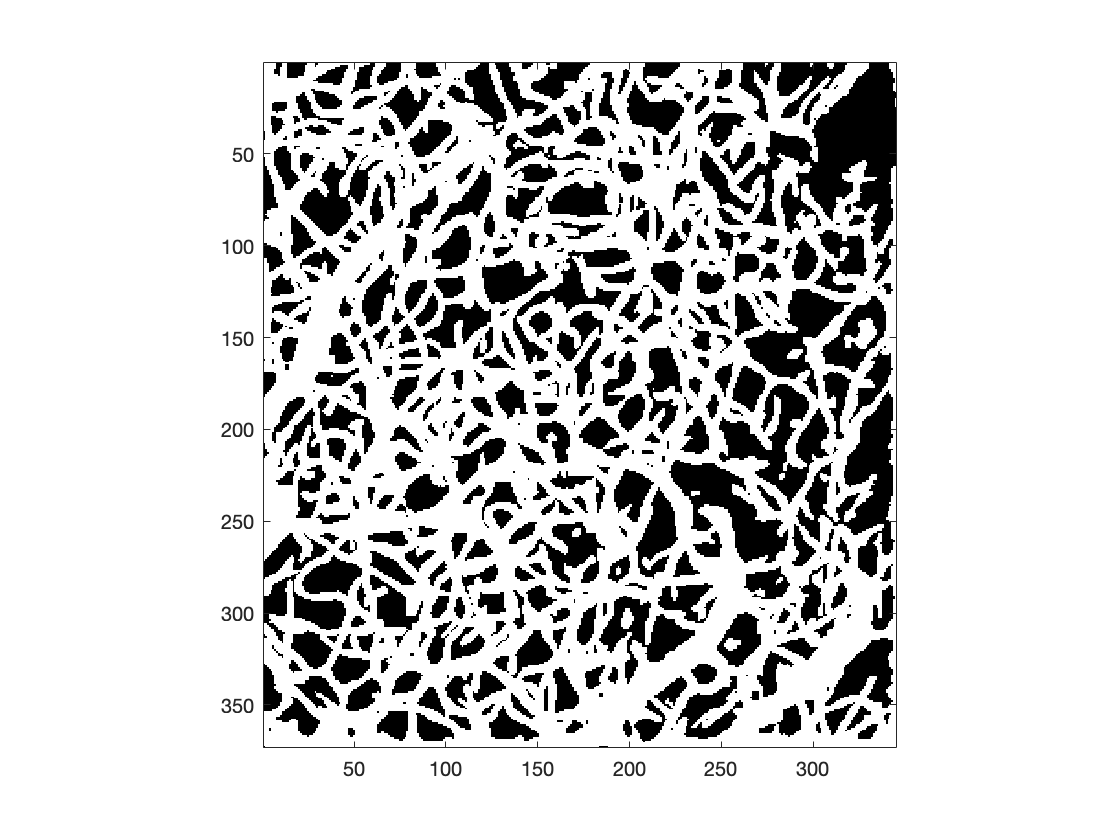

tic
load('corrnet_3layers.mat')
clear c;

c(:,:,:,1) = mat2gray(logDD);

Elapsed time is 468.871750 seconds.


c(:,:,:,2) = Enh;
c(:,:,:,3) = seg;
seg_corr = activations(corrnet,c,'dice', 'executionenvironment','cpu');
seg2 = max(seg_corr(1:s1,1:s2,1:s3,2),seg);
seg2 = seg2>0.3;
seg2 = imclose(seg2,ones(3,3,3));


%remove any small unconnected components
CC  = bwconncomp(seg2);
numPixels = cellfun(@numel,CC.PixelIdxList);
ind = find(numPixels > 100);
res = zeros(size(seg2));
for i = 1:length(ind)
    res(CC.PixelIdxList{ind(i)}) = 1;
end

mip = squeeze(max(res,[],1));
figure; imagesc(squeeze((mip)))
colormap(gray)
axis image
toc

## 7. Skeletonization

- Skeletonization following several steps: first the segmentation is thinned to produce a skeleton, which is then recentered. The skeleton is resized to produce an isotropic image. Spurious branches are removed based on how Gaussian they appear, and small unconnected branches are removed.

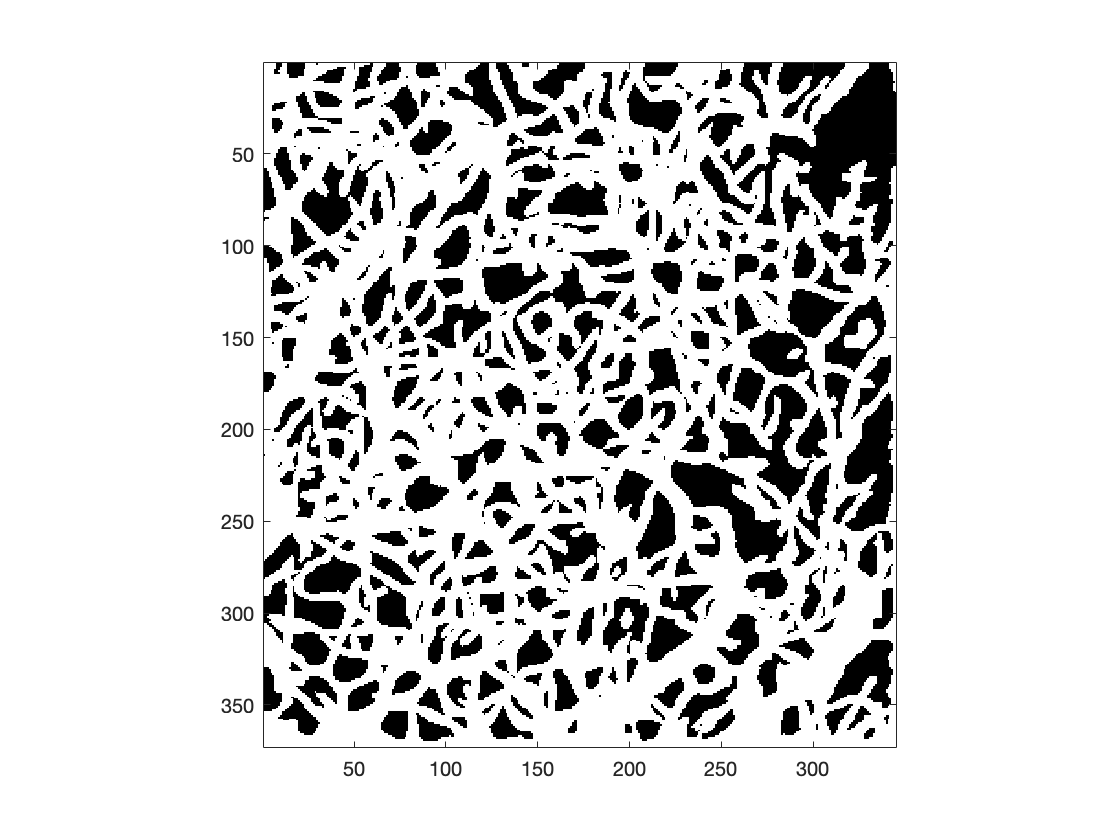


skel = make_skel(res,Enh); % ~50min %skeletonization and recentering


fszx = samp_interval;

fszy = samp_interval;

Elapsed time is 37.574198 seconds.



V = imresize3(Enh, [size(Enh,1), round(size(Enh,2)/fszx) round(size(Enh,3)/fszy)]); %resize to make isotropic
skel1 = imresize3(imdilate(skel, ones(3,3,3)), [size(Enh,1), round(size(Enh,2)/fszx) round(size(Enh,3)/fszy)]);
skel1 = skel1>0.5;
skel1 = imclose(skel1, ones(3,3,3));

Recentering #1...
Iteration: 1
Iteration: 2
Iteration: 3
Iteration: 4
Iteration: 5
Iteration: 6
Iteration: 7
Iteration: 8
Iteration: 9
Iteration: 10
Iteration: 11
Iteration: 12
Iteration: 13
Iteration: 14
Iteration: 15
Iteration: 16
Iteration: 17
Iteration: 18
Iteration: 19
Iteration: 20
Iteration: 21
Iteration: 22
Iteration: 23
Iteration: 24
Iteration: 25
Iteration: 26
Iteration: 27


skel1 = bwskel(skel1, "MinBranchLength",7);
S1 = rem_small(skel1); %~ 5min


%removing spurious branches

O = rem_nongauss_whole(S1,V); 


skel2 = rem_loop(S1,O, skel1); %removes spurious branches
skel3 = rem_seq(skel2) %removes endpoints < 7px
S3 = rem_small(skel3);

## 8. Automated vessel connection using Tensor Voting (Optional)

- This will aim to automatically connect endpoints based on tensor voting. This can connect many free ends, making manual correction take less time.

res2 = imresize3(res, [size(res,1), round(size(res,2)/fszx) round(size(res,3)/fszy)]); 

Processed: 200/889


Processed: 400/889


res2 = res2>0.1;
[skel3, Sc] = main_tensor_connect(skel3,S3,res2); %~1 min
S3 = rem_small(skel3);

## 8. Manual inspection and correction

You will be shown an image of about 100 x 100 pixels (en face slice) of the microangiogram with the vessel segments overlaid. 

- To scan through the depth: use z and x.

- To delete a vessel segment, click the vessel segment and press backspace.

- To "undo" a deleted vessel, press "v".

- Pay extra attention to vessels that are bounded by a red rectangle. These vessels have an unconnected endpoint.

- Once you click on a vessel, it will show you which other vessels it is connected to.

- To connect two vessel segments: 

-  Make sure that neither of the two vessels are currently selected (click away or on a different vessel if necessary), 

- Click on the button "Connect vessels"

- Click on the vessel segment with the endpoint you would like to connect, and then click on the second vessel you would like to connect it to.

- To create a new vessel segment:

- Press "enter".

- To create a point, click.

- If neccessary, use x and z to change the depth.

- Create connecting points by clicking. Lines between the points will be automatically created.

- To complete this process, press "enter" again.

- Don't forget to connect this vessel segment to other vessel segments by clicking "connect vessels"

- Once you are done with this square, close the window by clicking the 'x' in the right hand corner. A new window will automatically pop up. Repeat this process with the next window. 

- Once the entire image is processed, no new windows will pop up.

- If you wish to see the entire image at once, change the value of large_FOV to equal 1. Note that this may be slower.

- You can click "Quit" and it will save your work in the workspace. When you are ready to continue, just start this section again. To quit the entire analysis and return at a later stage, see Section 12.

large_FOV = 0; % or else make this equal to 1 for large field of view

if large_FOV == 1
    S = manual_inspection_large_FOV(S, V);
else
    S = manual_inspection(S, skel,V);
end
skel = seg2skel(S, V);

Creating scalar field
100/393
200/393
300/393
Connecting endpoints using scalar field


S = rem_small(skel);

## 9. Calculate vascular properties

- Vascular properties to be calculated: 

- Diameter

- Length

- Tortuosity

- Network properties

- Fractional dimension


Main_length; % ~2s
Main_diam; % ~15min
Main_tortuosity;  %~1min
Network_analysis; %~2min
[n,r] = boxcount(seg);
powfunc = fittype('n0*r^(-frac)',...
    'dependent',{'y'},'independent',{'r'},...
    'coefficients',{'n0','frac'});

100/762


200/762


pow_fit = fit(r',n',powfunc, 'startpoint', [max(n) 3]);
frac = pow_fit.frac;

## 10. Branching order: identify penetrating arterioles

- Please click on penetrating arterioles, which look like dark circles and are larger than capillaries.

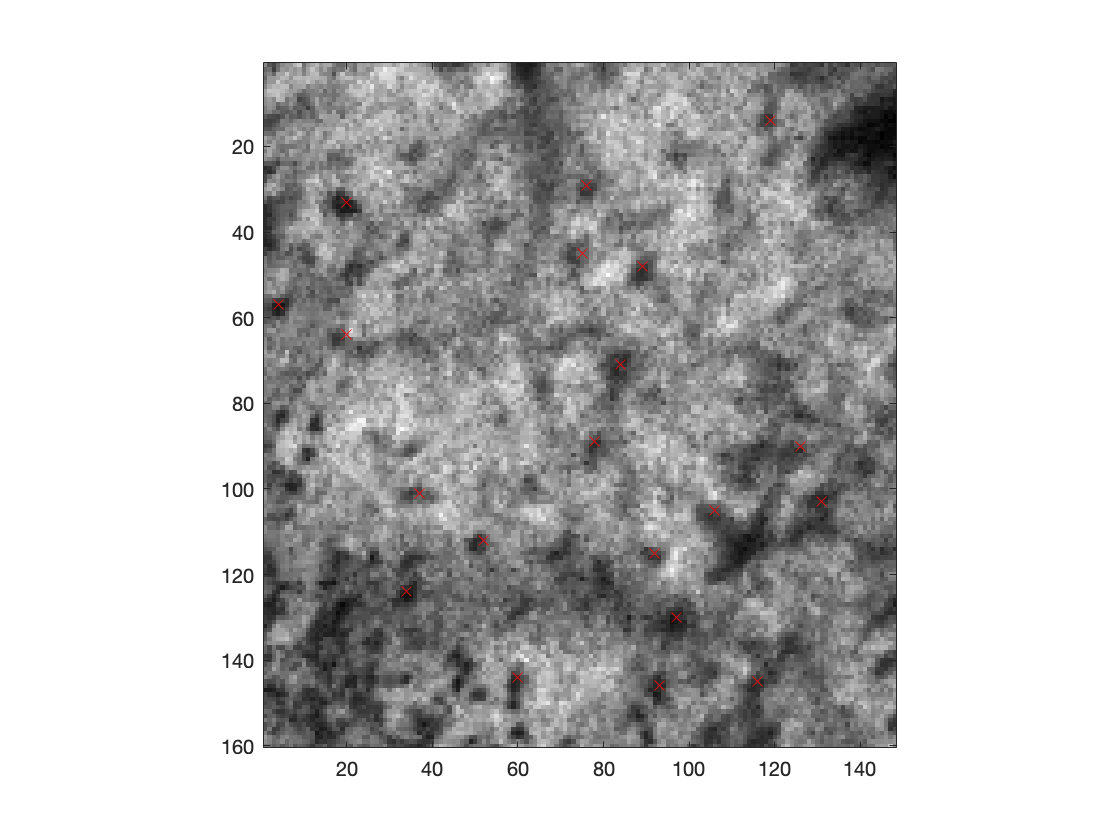

if branch_order == 'y'
    find_penetrating_art;
    mip = squeeze(min((II1(end-10:end,:,:)),[],1));
    figure; imagesc(squeeze((mip))) 
    colormap(gray)
    axis image
    hold on
    scatter(X,Y, 'x', 'r')

    branching_order; %~6min
end



## 11. Save analysis

Analysis will be saved as an excel file with 3 sheets:

- the first sheet provides diameter, length, and tortuosity

- the second sheet provides vessels per branching order

- the third sheet provides network properties

disp('Saving Analysis ...');

Saving Analysis ...



filename = [pathdata '/properties.xls'];
dat_geo = table(D, tort, full_l, 'variablenames', {'Diameter', 'Tortuosity', 'Length'});
writetable(dat_geo,filename)

Unable to save the workbook to file '/Users/sabinastefan/Downloads/Capillary Graphing Code (Public)/sstefan/microangiogram_analyzed/properties.xls'. Check that write permissions are available, there is sufficient disk space, and the file can be written to or created.


if branch_order == 'y'
    dat_branch = table(branch, 'variablenames', {'branching order'});
    writetable(dat_branch,filename,'sheet', 2);
end

dat_topo = table(metrics.clsness, metrics.btwness, metrics.assortativityByNode, metrics.eigenCentralities, 'variablenames',{'Closeness', 'Betweenness', 'Assortativity', 'EigenCentralities'});
writetable(dat_topo,filename,'sheet', 3);
dat_frac = table(frac, 'variablenames',{'fractal dimension'});
writetable(dat_frac, filename, 'sheet', 4)
save('-v7.3',[pathdata '.mat']);

disp('Analysis Saved.');

You may also want to export this analysis to a report in PDF. Run *Live Editor > Save > Export to PDF*.

## 12. Load a saved analysis for review.

Select an analysis to load. To review the loaded analysis, proceed to the following subsections. 

If you want to re-analyze the data, you can go back to the revelant sections  adjust the parameters, run again. 


disp('Loading Analysis ...');
load([pathdata '.mat']);
disp('Analysis Loaded.');